pos_0 = [1, 0, 0];
vel_0 = [1, 0, 0];
v_quat_0 = compact(quaternion([0, 0, 0], 'eulerd', 'xyz', 'frame'));

states_0 = [pos_0(:); vel_0(:); v_quat_0(:)]

states_0 =      1
     0
     0
     1
     0
     0
     1
     0
     0
     0


states_t = predict_state_transition(states_0, zeros(6, 1), 0, 1)

states_t =     2.0000
         0
         0
    1.0000
         0
   -1.0000
         0
    0.5774
    0.5774
    0.5774


pos_t = states_t(1:3);
vel_t = states_t(4:6);
v_quat_t = states_t(7:10);

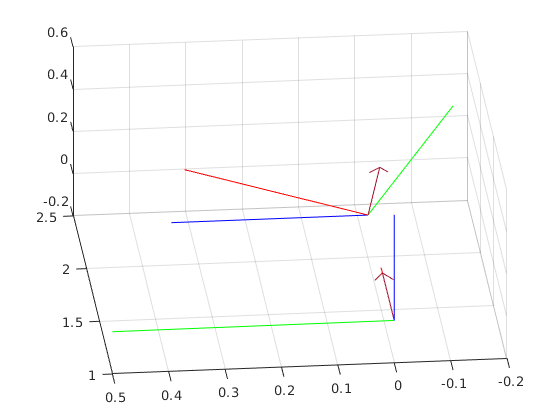

mat_posns = [pos_0; pos_t'];
mat_vels = [vel_0; vel_t'];
mat_v_quats = [v_quat_0; v_quat_t'];
mat_quats = quaternion(mat_v_quats);

mat_vels_world_frame = rotatepoint(mat_quats, mat_vels);

figure();
clf;
hold on

plotTransforms(mat_posns, mat_quats, 'framesize', 0.5)
quiver3(mat_posns(:, 1), mat_posns(:, 2), mat_posns(:, 3), mat_vels_world_frame(:, 1), mat_vels_world_frame(:, 2), mat_vels_world_frame(:, 3))
grid on